[~,folder,~] = fileparts(pwd);
assert(strcmpi(folder,"coil magnetic field"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Coil parameters

ai = 3.75e-3; % (m)
ao = 6.00e-3; % (m)
l  = 4.00e-3; % (m)
N  = 60;

r = linspace(0, ao*10, 100);
z = l * 0.45 * ones(size(r));

#### Compute MVP and MFD using different methods

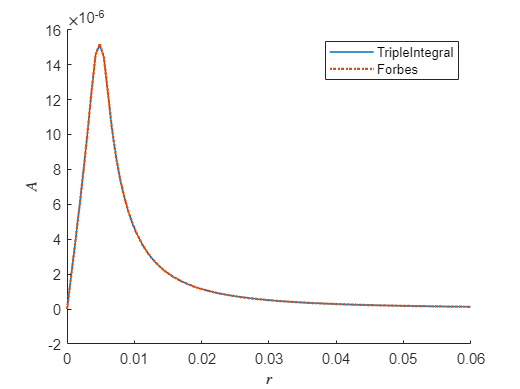

methods = ["TripleIntegral", "Forbes"];

linestyles = ["-" ":"];
linewidths = [1 1.5];

time_A = zeros(size(methods));
time_B = zeros(size(methods));

figure(1); hold on
figure(2); hold on
figure(3); hold on
for k = 1:length(methods)
    method = methods(k);

    A = zeros(size(r));
    Br = zeros(size(r));
    Bz = zeros(size(r));
    tic
    for i = 1:length(r)
        A(i) = CoilField("MVP", ai,ao,l,N, r(i),z(i), method);
    end
    time_A(k) = toc;
    
    tic
    for i = 1:length(r)
        B    = CoilField("MFD", ai,ao,l,N, r(i),z(i), method);
        Br(i) = B(1);
        Bz(i) = B(2);
    end
    time_B(k) = toc;

    figure(1)
    plot(r, A,  'DisplayName',method, 'LineStyle',linestyles(k), 'LineWidth',linewidths(k))
    figure(2)
    plot(r, Br, 'DisplayName',method, 'LineStyle',linestyles(k), 'LineWidth',linewidths(k))
    figure(3)
    plot(r, Bz, 'DisplayName',method, 'LineStyle',linestyles(k), 'LineWidth',linewidths(k))
end

figure(1)
xlabel('$r$',   'Interpreter','latex')
ylabel('$A$',   'Interpreter','latex')
legend

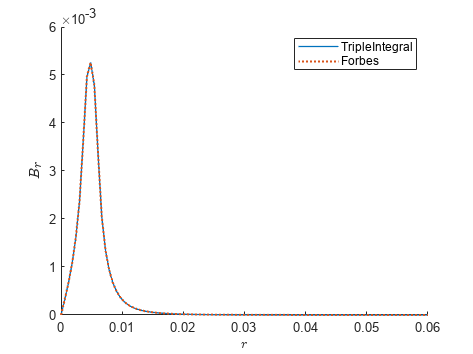

figure(2)
xlabel('$r$',   'Interpreter','latex')
ylabel('$B_r$', 'Interpreter','latex')
legend

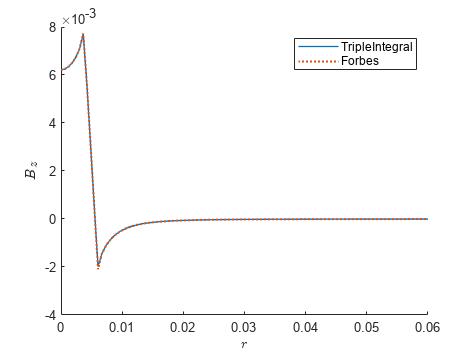

figure(3)
xlabel('$r$',   'Interpreter','latex')
ylabel('$B_z$', 'Interpreter','latex')
legend


T = table(methods.', time_A.', time_B.', 'VariableNames', ["Method" "Time A (s)" "Time B (s)"]);
disp(T)

         Method         Time A (s)    Time B (s)
    ________________    __________    __________

    "TripleIntegral"       1.6695       10.831  
    "Forbes"             0.068799      0.13078  

